clear, clc, format short g


data = importdata("dati_punto_3.mat");
data2 = importdata("dati_punto_2.mat");

U_H = data.U_H;
U_phi = data.U_phi;
H = data.H;
phi = data.phi;
ur_H = data.ur_H;
u_phi = data.u_phi;
C_H = data2.C_H;
C_phi = data2.C_phi;
R = data.R;
fx = data.fx;

## Parte 4

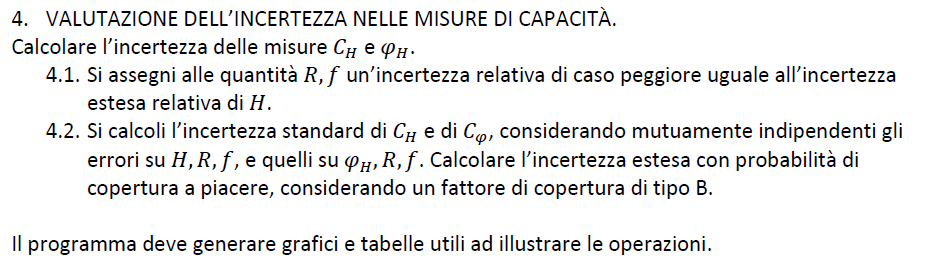

## Valutazione dell'incertezza nelle misure di Capacità

% Calcolo incertezza relativa estesa sulla misura di risposta in ampiezza
Ur_H = U_H/abs(H)

Ur_H =     0.0051436



% Imposto l'incertazza relativa di caso peggiore
Ur_100_R = Ur_H;
Ur_100_f = Ur_H;

% Stima dell'incertezza standard, supponendo in ingresso distribuzione uniforme poiché 
% note le incertezze di caso peggiore relative
ur_f = Ur_100_f/sqrt(3)

ur_f =     0.0029696


ur_R = Ur_100_R/sqrt(3)

ur_R =     0.0029696



% definizione del vettore delle incertezze
ur_x = [ur_H u_phi/abs(phi) ur_R ur_f]

ur_x =     0.0026211     0.017287    0.0029696    0.0029696



% definizione dei valori effettivi di misura:
x = [H phi R fx]';

## Calcolo simbolico dei coefficienti di sensibilità relativi per la misura di capacità 

syms C_H_sym R_sym f_sym H_sym C_phi_sym phi_sym x_sym CrH_sym CrPhi_sym as real

% definisco la funzione di calcolo della capacità nota la risposta in
% ampiezza
C_H_sym = sqrt(1 - H_sym^2)/H_sym*(1/(2*pi*R_sym*f_sym))

$$C\_H\_sym = \frac{\sqrt{1-{H_{\mathrm{sym}}}^{2}}}{2\,H_{\mathrm{sym}}\,R_{\mathrm{sym}}\,f_{\mathrm{sym}}\,\pi }$$


% definisco la funzione di calcolo della capacità nota la risposta di fase
C_phi_sym = tan(-phi_sym)*(1/(2*pi*R_sym*f_sym))

$$C\_phi\_sym = -\frac{\tan\left(\varphi_{\mathrm{sym}}\right)}{2\,R_{\mathrm{sym}}\,f_{\mathrm{sym}}\,\pi }$$


% definisco il vettore theta delle equazioni di calcolo delle capacità:
theta = [C_H_sym; C_phi_sym]

$$theta = \left(\begin{array}{c} \frac{\sqrt{1-{H_{\mathrm{sym}}}^{2}}}{2\,H_{\mathrm{sym}}\,R_{\mathrm{sym}}\,f_{\mathrm{sym}}\,\pi }\\ -\frac{\tan\left(\varphi_{\mathrm{sym}}\right)}{2\,R_{\mathrm{sym}}\,f_{\mathrm{sym}}\,\pi } \end{array}\right)$$


% definisco il vettore delle misure in ingresso per il calcolo
x_sym = [H_sym  phi_sym R_sym f_sym]'

$$x\_sym = \left(\begin{array}{c} H_{\mathrm{sym}}\\ \varphi_{\mathrm{sym}}\\ R_{\mathrm{sym}}\\ f_{\mathrm{sym}} \end{array}\right)$$


% calcolo coefficienti di sensibiltà relativi
Cr_sym = simplify(jacobian(log(theta), x_sym).*x_sym')

$$Cr\_sym = \left(\begin{array}{cccc} \frac{1}{{H_{\mathrm{sym}}}^{2}-1} & 0 & -1 & -1\\ 0 & \frac{2\,\varphi_{\mathrm{sym}}}{\sin\left(2\,\varphi_{\mathrm{sym}}\right)} & -1 & -1 \end{array}\right)$$


% calcolo dei valori effettivi dei coefficienti di sensibilità relativi:
Cr = double(subs(Cr_sym,x_sym,x))

Cr =       -38.716            0           -1           -1
            0       1.0158           -1           -1


## Stima dell'incertezza standard, supponendo in ingresso distribuzione uniforme poiché note le incertezze di caso peggiore relative

% stima matrice covarianza relativa in ingresso per la misura della
% capacità 
sigmar = diag(ur_x)*diag(ur_x)

sigmar =    6.8703e-06            0            0            0
            0   0.00029883            0            0
            0            0   8.8188e-06            0
            0            0            0   8.8188e-06



% stima matrice covarianza relativa in uscita
sigmar_theta = Cr*sigmar*Cr'

sigmar_theta =      0.010316   1.7638e-05
   1.7638e-05   0.00032595



% stima incertezza standard in uscita
ur_theta = sqrt(diag(sigmar_theta))

ur_theta =       0.10157
     0.018054


ur_CH = ur_theta(1)

ur_CH =       0.10157


ur_Cphi = ur_theta(2)

ur_Cphi =      0.018054



% stima incertezza assoluta della misura di capacità in uscita, noti
% l'incertezza relativa in uscita ed il modulo della capacità, sia per H
% che per phi:
u_CH = ur_theta(1) * abs(C_H)

u_CH =    1.1173e-09


u_CPhi = ur_theta(2) * abs(C_phi)

u_CPhi =    2.6844e-10


## Calcolo incertezze estese con cp = 90%

% stima incertezze estese con valutazioe di tipo B (dunque usando norminv)
k = norminv((1+0.9)/2)

k =        1.6449



U_90_C_H = k*u_CH

U_90_C_H =    1.8378e-09



U_90_C_Phi = k*u_CPhi

U_90_C_Phi =    4.4154e-10


## Analizziamo i dati ottenuti in una Tabella

misure=[C_H,C_phi]';
u_r_percentuali = ur_theta*100;
u = [u_CH, u_CPhi]';
U_90 = [U_90_C_H, U_90_C_Phi]';
rows = [{'C_H'}, {'C_phi'}]';

T = table(misure, u_r_percentuali, u, U_90,'RowNames',rows)

T = 2×4 table
               misure      u_r_percentuali        u            U_90   
             __________    _______________    __________    __________

    C_H      1.1001e-08        10.157         1.1173e-09    1.8378e-09
    C_phi    1.4868e-08        1.8054         2.6844e-10    4.4154e-10
